# Lab 1

## Prepare

Please go through the live scripts: MatlabReview and BasicAudioImage.

## Q1. Sine Wave

Create a cosine wave with a frequency of 1 kHz, sampled at 48 kHz, with a duration of 0.5 seconds and 0 phase offset. Play the sine wave and listen to check that it is correct. Plot the first three periods of your cosine signal with the correct time axis. Label your plot and label the axes.

**Solution**

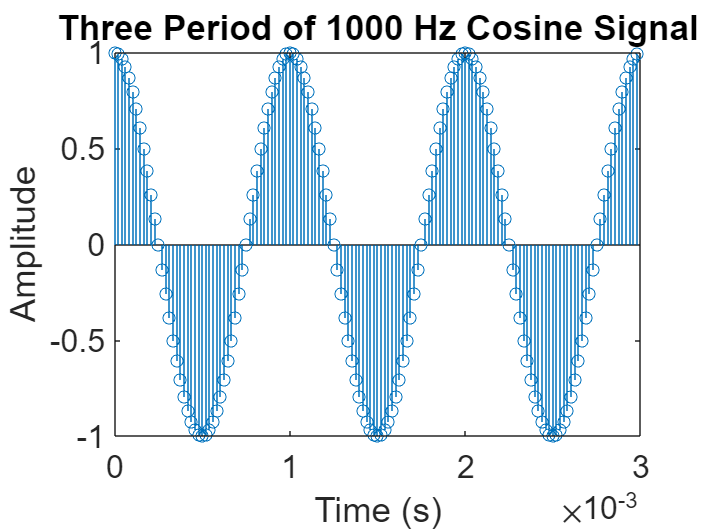

% Create the time axis using (starttime:sampleperiod:endtime)
% 1/48000 is the sample period
% 0.5 is in seconds, total time
tSamp = 0:1/48000:0.5;
% Create a 1 kHz cosine signal
% Same as cos(2pift)
cosSig = cos(2*pi*1000*tSamp);
sound(cosSig,48000)
% Calculate number of samples in three periods
% first 3 periods is period = 1/f f = 1000, Therefore: 3 * 1/f * fsamp
sampNum3Pd = ceil(1/1000 * 3 * 48000);
% create a plot
figure ;
% (1 : cutoffSampNum) displays the first cutoffSampNum Samples
stem(tSamp(1:sampNum3Pd),cosSig(1:sampNum3Pd))
set(gca,'fontsize',16)
title('Three Period of 1000 Hz Cosine Signal')
xlabel("Time (s)")
ylabel("Amplitude")

## Q2. Periodic Signals

The complex exponential sequence $e^{j\,\omega_0\,n}$ or the sinusoidal sequence $\cos(\omega_0\,n)$are periodic if the normalized frequency $f_0=\frac{\omega_0}{2\pi}$ is a rational number; that is $f_0 = \frac{K}{N}$, where K and N are integers.

- Prove the result (write your answer using Latex math style)

- Generate exp(j0.1$\pi$n), -100 < n < 100. Plot its real and imaginary parts using the stem function. Is this sequence periodic? If it is, what is the fundamental period? From the examination of the plot, what interpretation can you give to the integers K and N?

- Generate and plot cos(0.1n), 0 < n < 63. Is this sequence periodic? Plot the sequence for 63 < n < 126. Plot the difference between these two regions of the sequence

## Solution

1. $e^{j\omega_0(n+N)} => e^{j2\pi f_0N} = 1\ then\ since\ e^{j2\pi L} = 1, f_0N = integer = K, therefore\ f_0 = \frac{K}{N}$

2.

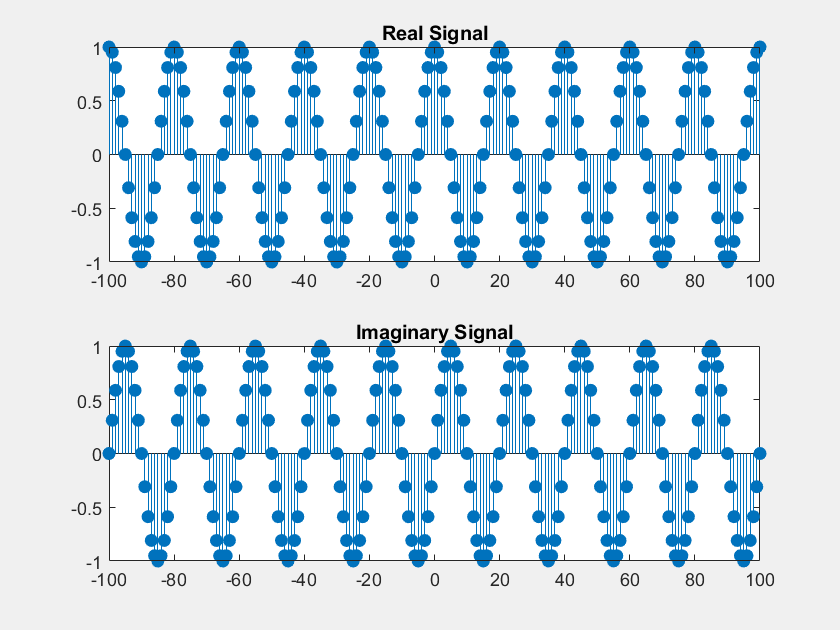

% Q2 code section
% Create n from -100 to 100 
n = (-100:100);
sig = exp(1j * n * pi * 0.1);
figure;
set(gcf, 'Visible', 'On');
subplot(2, 1, 1);
stem(n, real(sig), 'filled');
title('Real Signal')
set(gcf, 'Visible', 'On');
subplot(2, 1, 2);
stem(n, imag(sig), 'filled');
title('Imaginary Signal')


% Period is 20 -> N is the period 
N = 20

N = 20

tmp = sig(1:N) - sig(N+1:2*N)

tmp = 1.0e-14 *

   0.0000 - 0.3308i   0.0999 - 0.3164i  -0.0222 + 0.0222i  -0.0222 + 0.0222i  -0.0278 + 0.0111i  -0.0245 + 0.0000i  -0.0222 - 0.0111i  -0.2998 - 0.2220i  -0.0222 - 0.0222i  -0.0111 - 0.0222i   0.0000 + 0.3308i   0.0111 - 0.0222i   0.2220 - 0.3109i   0.3109 - 0.2220i   0.3664 - 0.1110i   0.0245 + 0.0000i  -0.3164 - 0.0999i  -0.2776 - 0.1998i   0.0111 + 0.0111i   0.0111 + 0.0222i


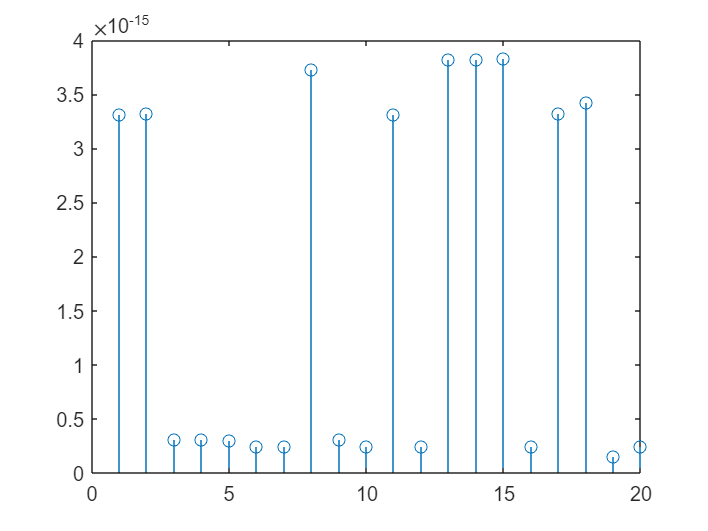

figure
stem(abs(tmp))


% 1/2pi = f_0N ceil(1/2pi) = K, f_0 = 1/20 which is correct.

 3.

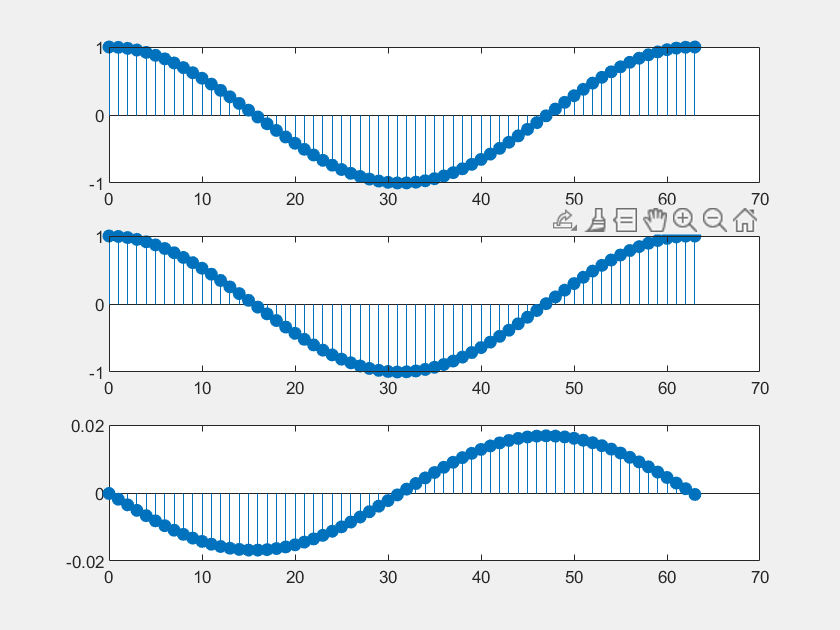

n2 = (0:63);
sig1 = cos(0.1 * n2);
figure;
set(gcf, 'Visible', 'On');
subplot(3, 1, 1);
stem(n2, sig1, 'filled');

sig2 = cos(0.1 * (n2 + 63));
set(gcf, 'Visible', 'On');
subplot(3, 1, 2);
stem(n2, sig2, 'filled');

sig3 = sig2 - sig1;
set(gcf, 'Visible', 'On');
subplot(3, 1, 3);
stem(n2, sig3, 'filled');

## Q3. Convolution

Write a MATLAB program that explicitly computes the convolution $y = x[n] * h[n]$of the following two sequences: x[n], h[n] (given below). Your program should employ a for loop and use the sigfold, sigshift, sigmult functions.

What is the value of y[4] ?

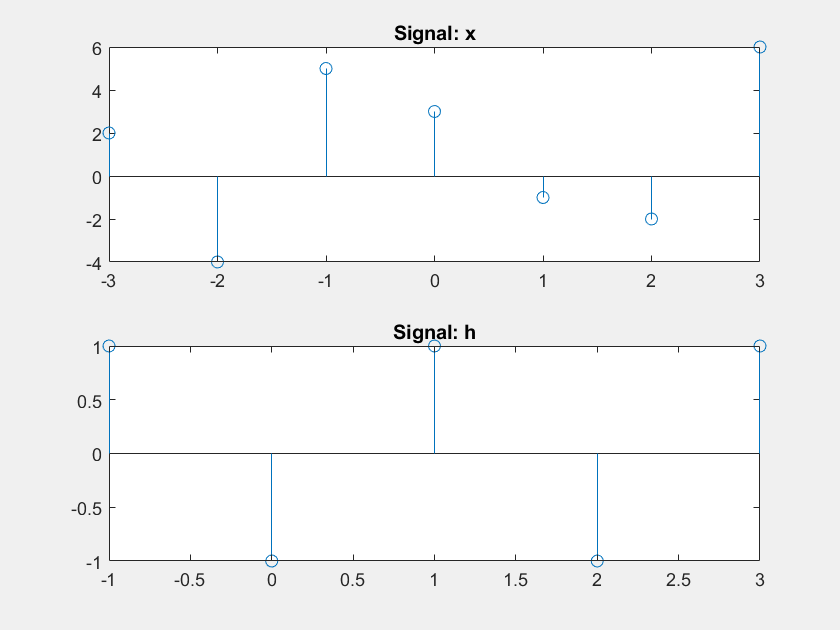

close all
nx = (-3:3) ;
x = [2,-4,5,3,-1,-2,6] ;
nh = (-1:3) ;
h = [1,-1,1,-1,1] ;
figure
set(gcf,'Visible','On')
subplot(2,1,1)
stem(nx,x)
title('Signal: x')
subplot(2,1,2)
stem(nh,h)
title('Signal: h')

## Solution

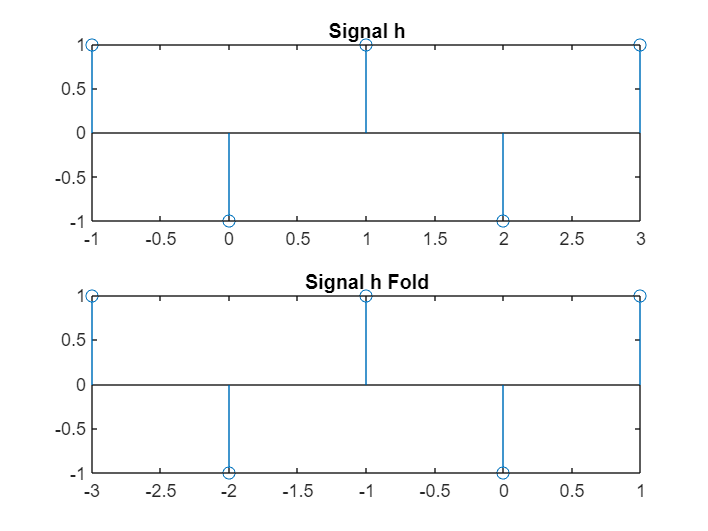

% decide to fold signal h -> ->
[hFold, nhF] = sigfold(h, nh);
figure
subplot(2,1,1)
stem(nh,h)
title('Signal h')
subplot(2,1,2)
stem(nhF,hFold)
title('Signal h Fold')


ny = (-4:1:6)

ny =     -4    -3    -2    -1     0     1     2     3     4     5     6


fh = figure

fh =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [573 444 560 420]
       Units: 'pixels'

  Show all properties


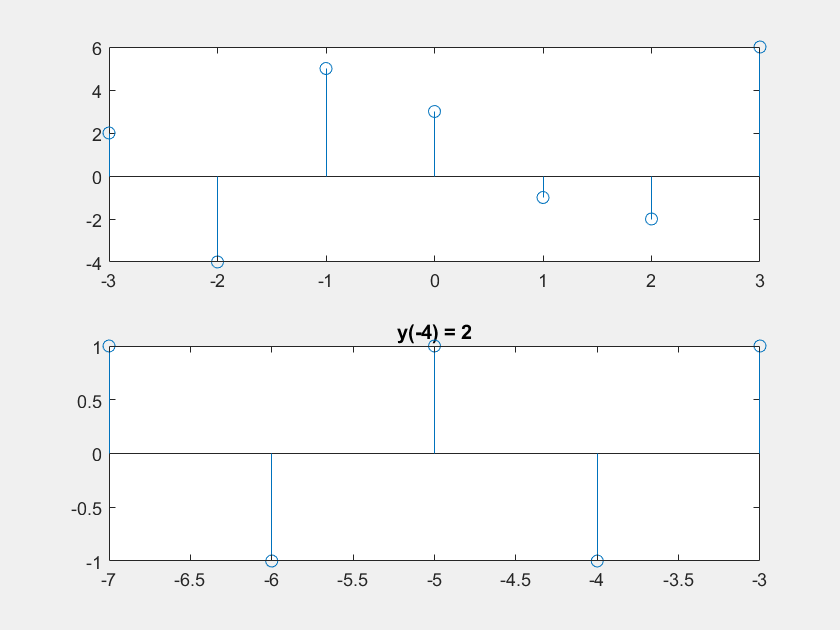

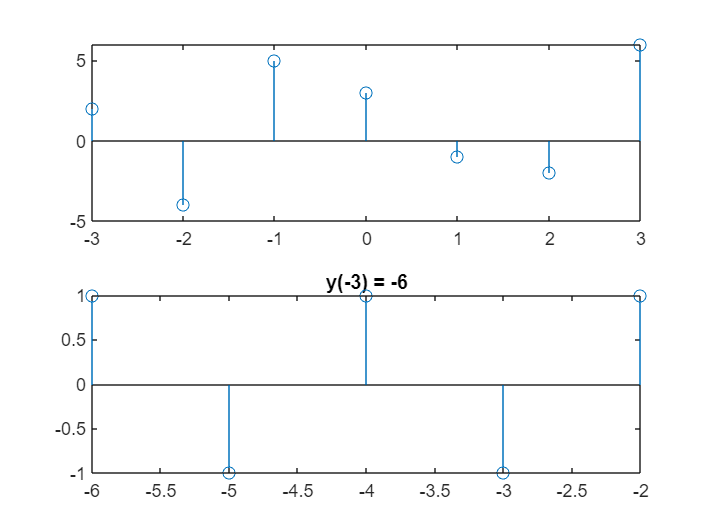

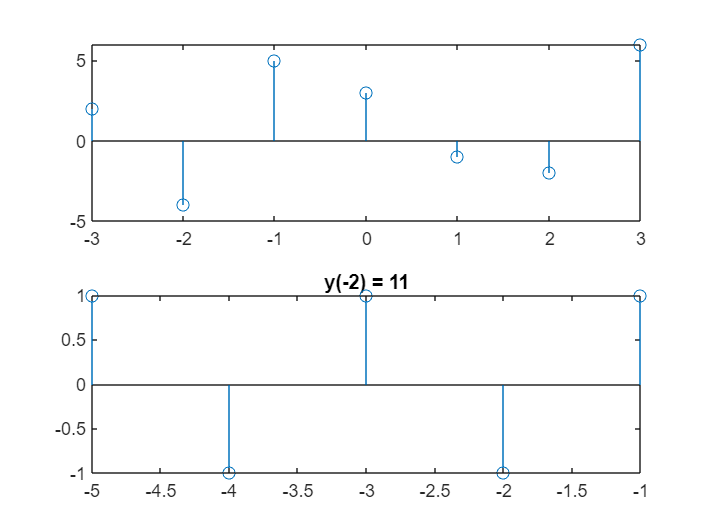

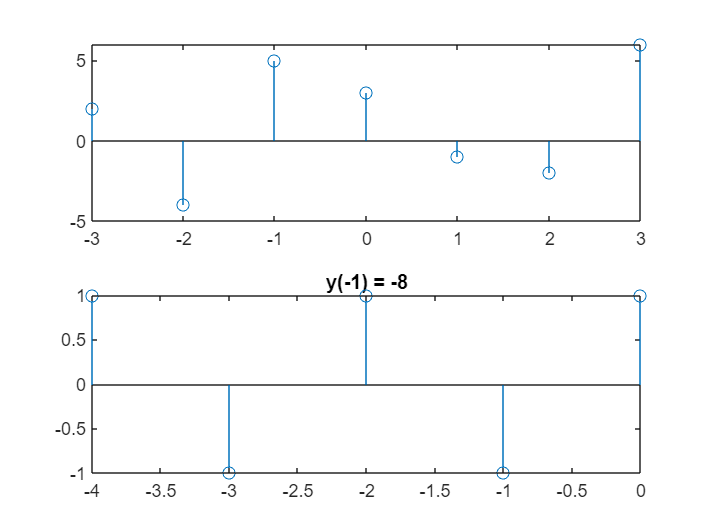

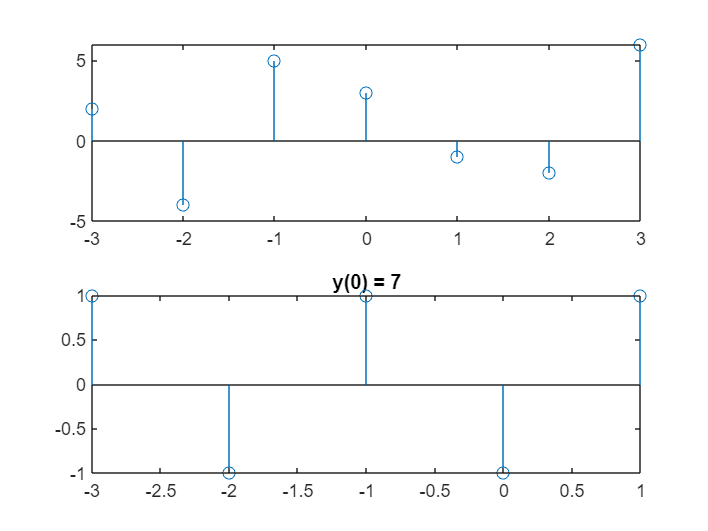

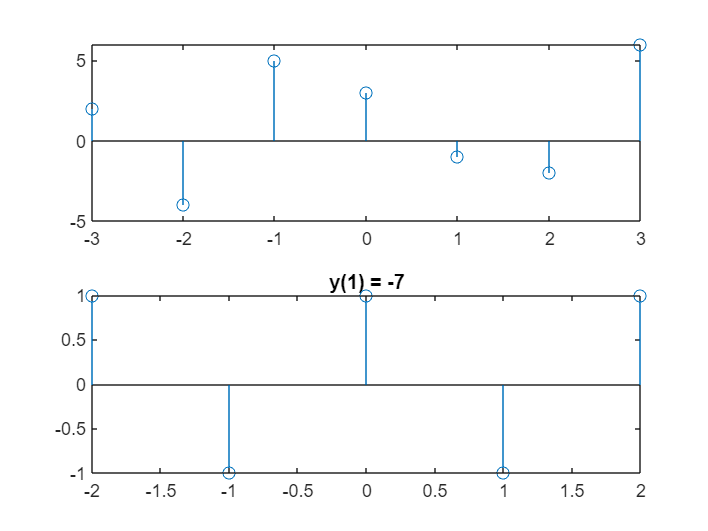

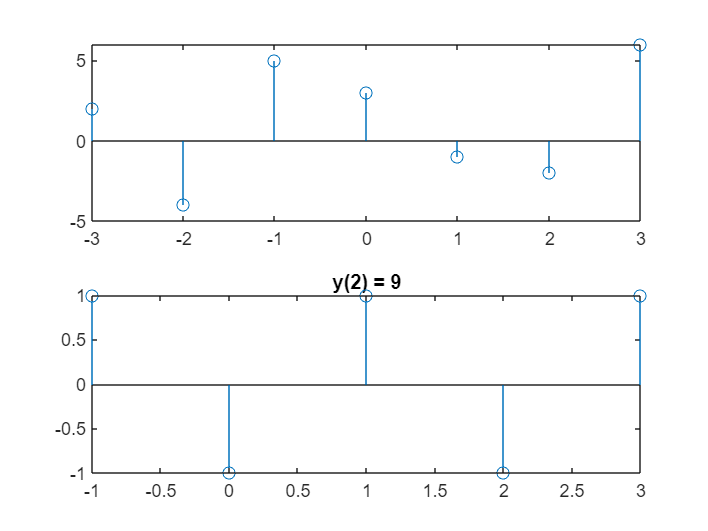

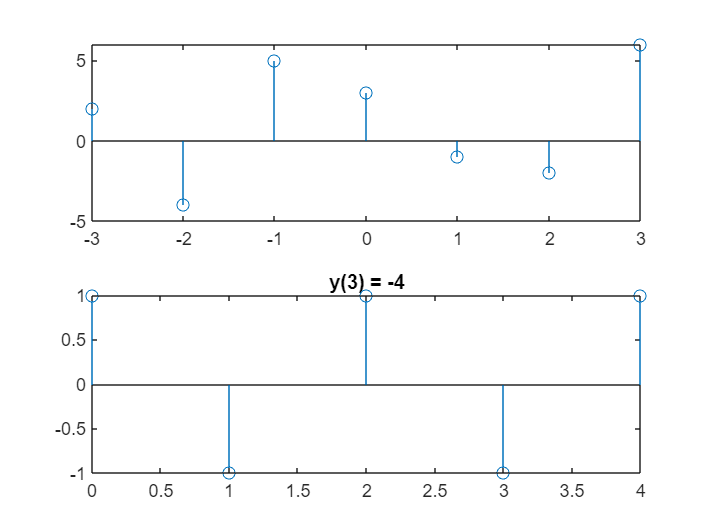

for I = ny
    % Convolution Step 1
    figure
    set(fh,'Visible','On')
    subplot(2,1,1)
    stem(nx,x) ;
    [hFShift, nShift] = sigshift(hFold, nhF, I); % Use sigshift() ;
    subplot(2,1,2)
    stem(nShift, hFShift)
    % have to add 5 so index of y[n] starts at 1
    % for Matlab ny = (-4:6)
    y(I+5) = sum(sigmult(x, nx, hFShift, nShift)); % Use sum(sigmult()) ;
    title(['y(',num2str(I),') = ',num2str(y(I+5))])
    %pause(0.5)
end

## Q4. Convolution as a Matrix-Vector Operation

When sequences x[n] and h[n] are of finite duration, then their linear convolution y[n] = x[n] * h[n] can be implemented using matrix-vector multiplication. In this case, we let y[n] and x[n] be column vectors and we have:


$$y = \mathbf{H}\,x$$


where linear shifts in h[n-k] are arranged as rows in the matrix **H**. The matrix **H** has an interesting structure and is called a Toeplitz matrix.

To investigate these issues do the following:

- Let x[n] = {1,2,3,4,5} for n = {0,1,2,3,4} and h[n] = {6,7,8,9} for n = {0,1,2,3}. Determine the linear convolution, y[n], of these two sequences. You can use the conv_m function.

- Express x[n] as a column vector; y[n] as a column vector. Determine the matrix **H**..

- Characterize the matrix **H**.

- Describe the first column and first row of **H**.

- Complete the MATLAB function conv_tp.m Use the MATLAB function toeplitz.

## Solution

1.

2.

3.

4.

5.

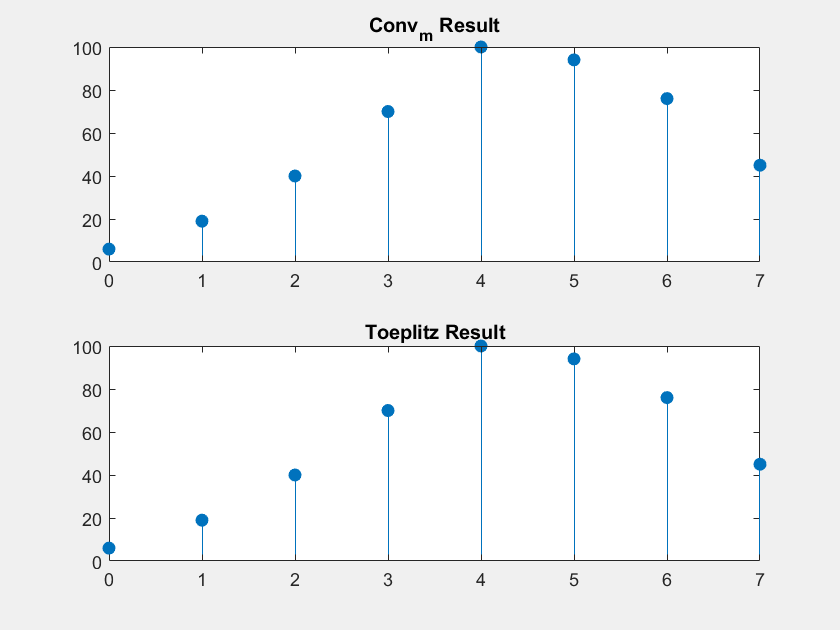

% Set up x and h
% transpose to represent it as a column vector
x = transpose(1:1:5);
nx = (0:1:4);
h = transpose(6:1:9);
nh = (0:1:3);
[y_m, ny] = conv_m(x,nx,h,nh);

% plot y
figure;
set(gcf, 'Visible', 'On');
subplot(2, 1, 1);
stem(ny, y_m, 'filled');
title('Conv_m Result');

% Q5.
% y_tp = output sequence in column format
% H = Toeplitz convolution matrix
% hc is first column of H and hr is first row of H
% h = impulse response in column format
% x = input sequence in column format
Nx = length(x) ; Nh = length(h) ;
hc = [6, 7, 8, 9, 0, 0, 0, 0]; hr = [6, 0, 0, 0, 0];
H = toeplitz(hc, hr); % Use toeplitz(hc,hr);
y_tp = H*x;

set(gcf, 'Visible', 'On');
subplot(2, 1, 2);
stem(ny, y_tp, 'filled');
title("Toeplitz Result");